# Scale-invariant Feature Transforma (SIFT) 

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2020-12-26

### Second Derivative of Gaussiance

clear; close all; clc;

% https://en.wikipedia.org/wiki/Mexican_hat_wavelet

x= -10:0.01:10;
sigma = 1;


$$g\left(x\right)=-\frac{1}{\sigma \sqrt{2\pi }\;}\exp^{-\frac{x^2 }{2\sigma^2 }\;}$$


g = 1/(sigma*sqrt(2*pi))*exp(-1/2*((x)/sigma).^2);



$${g^{\prime } }^{\prime } \left(x\right)=-\frac{1}{\sigma \sqrt{2\pi }\;}\left(\frac{x^{2\;} }{\sigma^{4\;} }-\frac{1}{\sigma^2 }\right)\exp^{-\frac{x^2 }{2\sigma^2 }\;}$$


gpp = -1/(sigma*sqrt(2*pi))*(x.^2/sigma^4-1/sigma^2).*exp(-1/2*((x)/sigma).^2); % second derivative

% first zero crossing when sigma or -sigma

fig1 = figure(1);
set(fig1,'Position', [100 100 800 250]);

subplot(121); plot(x, g, 'b', 'linewidth', 2); hold on;
errorbar(0, 0, 3*sigma, 'horizontal', 'linewidth', 2, 'color', 'r');
text(0, 0,'\bf 6\sigma','fontSize', 14, 'HorizontalAlignment', 'center', 'VerticalAlignment','top')
grid on; hold off;
xlabel('\bf x-axis'); 
ylabel('\bf g(x)'); ylim([-0.08 max(g)])
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold');

gpp = -1/(sigma*sqrt(2*pi)*sigma^3)*(1-x.^2/sigma^2).*exp(-1/2*((x)/sigma).^2);

subplot(122); plot(x, gpp, 'b', 'linewidth', 2); hold on;
plot(sigma, 0, 'or', 'linewidth', 3); 
text(sigma, -0.02,'\bf \sigma ','fontSize', 14, 'HorizontalAlignment', 'left', 'VerticalAlignment','top')
grid on; hold off;
xlabel('\bf x-axis'); 
ylabel('\bf g''''(x)'); ylim([min(gpp) 0.3])
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold');

### Blob Filter (1D)

%% 1D example
fig2 = figure(2);

sig = zeros(1,400);
sig(150:250) = 1;

subplot(711); plot(1:numel(sig), sig, 'linewidth', 1.5); axis tight;
ylabel('\bf f(x)','Interpreter', 'latex'); xlim([0 numel(sig)]);
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

windSize = 61;
h = gausswin(windSize,3);
subplot(712); plot(1:numel(h), h, 'linewidth', 1.5); axis tight;
ylabel('\bf h(x)','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

fh = conv(sig,h,'valid');
subplot(713); plot(windSize/2:numel(fh)+windSize/2-1, fh, 'linewidth', 1.5); axis tight;
ylabel('\bf f * h','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

h = gausswin(windSize,3);
diff_h = diff(h);
subplot(714); plot(1:numel(diff_h), diff_h, 'linewidth', 1.5); axis tight;
ylabel('\bf h''(x)','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

fh = conv(sig,diff_h,'valid');
subplot(715); plot(windSize/2:numel(fh)+windSize/2-1, fh, 'linewidth', 1.5); axis tight;
ylabel('\bf f * h''','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

diff_h2 = diff(diff(h));
subplot(716); plot(1:numel(diff_h2), diff_h2, 'linewidth', 1.5); axis tight;
ylabel('\bf h''''(x)','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

fh2 = conv(sig,diff_h2,'valid');
subplot(717); plot(windSize/2:numel(fh2)+windSize/2-1, fh2, 'linewidth', 1.5); axis tight;
ylabel('\bf f * h'''' ','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')
set(fig2,'Position', [100 100 900 800]);

%%
fig3 = figure(3);

sig = zeros(1,400);
sig(190:210) = 1;

subplot(711); plot(1:numel(sig), sig, 'linewidth', 1.5); axis tight;
ylabel('\bf f(x)','Interpreter', 'latex'); xlim([0 numel(sig)]);
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

windSize = 61;
h = gausswin(windSize,3);
subplot(712); plot(1:numel(h), h, 'linewidth', 1.5); axis tight;
ylabel('\bf h(x)','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

fh = conv(sig,h,'valid');
subplot(713); plot(windSize/2:numel(fh)+windSize/2-1, fh, 'linewidth', 1.5); axis tight;
ylabel('\bf f * h','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

h = gausswin(windSize,3);
diff_h = diff(h);
subplot(714); plot(1:numel(diff_h), diff_h, 'linewidth', 1.5); axis tight;
ylabel('\bf h''(x)','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

fh = conv(sig,diff_h,'valid');
subplot(715); plot(windSize/2:numel(fh)+windSize/2-1, fh, 'linewidth', 1.5); axis tight;
ylabel('\bf f * h''','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

diff_h2 = diff(diff(h));
subplot(716); plot(1:numel(diff_h2), diff_h2, 'linewidth', 1.5); axis tight;
ylabel('\bf h''''(x)','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

fh2 = conv(sig,diff_h2,'valid');
subplot(717); plot(windSize/2:numel(fh2)+windSize/2-1, fh2, 'linewidth', 1.5); axis tight;
ylabel('\bf f * h'''' ','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')
set(fig3,'Position', [100 100 900 800]);

%%
fig4 = figure(4);

sig = zeros(1,400);
sig(195:205) = 1;

subplot(711); plot(1:numel(sig), sig, 'linewidth', 1.5); axis tight;
ylabel('\bf f(x)','Interpreter', 'latex'); xlim([0 numel(sig)]);
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

windSize = 61;
h = gausswin(windSize,3);
subplot(712); plot(1:numel(h), h, 'linewidth', 1.5); axis tight;
ylabel('\bf h(x)','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

fh = conv(sig,h,'valid');
subplot(713); plot(windSize/2:numel(fh)+windSize/2-1, fh, 'linewidth', 1.5); axis tight;
ylabel('\bf f * h','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

h = gausswin(windSize,3);
diff_h = diff(h);
subplot(714); plot(1:numel(diff_h), diff_h, 'linewidth', 1.5); axis tight;
ylabel('\bf h''(x)','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

fh = conv(sig,diff_h,'valid');
subplot(715); plot(windSize/2:numel(fh)+windSize/2-1, fh, 'linewidth', 1.5); axis tight;
ylabel('\bf f * h''','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

diff_h2 = diff(diff(h));
subplot(716); plot(1:numel(diff_h2), diff_h2, 'linewidth', 1.5); axis tight;
ylabel('\bf h''''(x)','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')

fh2 = conv(sig,diff_h2,'valid');
subplot(717); plot(windSize/2:numel(fh2)+windSize/2-1, fh2, 'linewidth', 1.5); axis tight;
ylabel('\bf f * h'''' ','Interpreter', 'latex'); xlim([0 numel(sig)])
hYLabel = get(gca,'YLabel');grid on; grid minor;
set(hYLabel,'rotation',0,'VerticalAlignment','middle', 'HorizontalAlignment','right')
set(fig4,'Position', [100 100 900 800]);

### Blob Filter (2D)

clear; close all; clc;

% https://pixabay.com/en/sunflower-yellow-flower-832793/
img = imread('sunflower-832793_1920_gray.jpg');
img = im2double(img);
img = imresize(img,0.3);

h1 = fspecial('log',5,1);
h2 = fspecial('log',10,2);
h3 = fspecial('log',15,3);
h4 = fspecial('log',20,4);

fig1 = figure(1);
set(fig1,'Position', [100 100 800 500]);
subplot(221); imshow(mat2gray(h1));
subplot(222); imshow(mat2gray(h2));
subplot(223); imshow(mat2gray(h3));
subplot(224); imshow(mat2gray(h4));

fig2 = figure(2);
set(fig2,'Position', [100 100 1200 500]);
subplot(221); imshow(mat2gray(imfilter(img,h1)));
subplot(222); imshow(mat2gray(imfilter(img,h2)));
subplot(223); imshow(mat2gray(imfilter(img,h3)));
subplot(224); imshow(mat2gray(imfilter(img,h4)));

### Comparison of DoG and LoG

clear; close all; clc;

% https://pixabay.com/en/sunflower-yellow-flower-832793/
img = imread('sunflower-832793_1920_gray.jpg');
img = im2double(img);
img = imresize(img,0.3);

sigma = 2;
k = 1.1;

h_gaussian1 = fspecial('gaussian',10, sigma); % gaussian filter
h_gaussian2 = fspecial('gaussian',10, sigma*k); % gaussian filter
h_log = fspecial('log',10, sigma); % LoG filter

img_log = imfilter(img, h_log);
img_g1 = imfilter(img, h_gaussian1);
img_g2 = imfilter(img, h_gaussian2);

fig1 = figure(1);
set(fig1,'Position', [100 100 800 500]);
subplot(221); imshow(mat2gray(img_g1));
subplot(222); imshow(mat2gray(img_g2));

fig2 = figure(2);
set(fig2,'Position', [100 100 800 500]);
subplot(221); imshow(mat2gray(img_log));
subplot(222); imshow(mat2gray((img_g2-img_g1)/sigma/sigma/(k-1)));

### Laplacian of Gaussian (Filter Size)

clear; close all; clc;

x= -10:0.01:10;
sigma = 1;
g = 1/(sigma*sqrt(2*pi))*exp(-1/2*((x)/sigma).^2);

% https://en.wikipedia.org/wiki/68%E2%80%9395%E2%80%9399.7_rule

fig1 = figure(1);
set(fig1,'Position', [100 100 350 500]);

subplot(211); plot(x, g, 'b', 'linewidth', 2); hold on;
errorbar(0, 0, 3*sigma, 'horizontal', 'linewidth', 2, 'color', 'r');
text(0, 0,'\bf 6\sigma','fontSize', 8, 'HorizontalAlignment', 'center', 'VerticalAlignment','top')
grid on; hold off;
xlabel('\bf x-axis'); 
ylabel('\bf g(x)'); ylim([-0.05 max(g)])
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold');

gpp = -1/(sigma*sqrt(2*pi)*sigma^3)*(1-x.^2/sigma^2).*exp(-1/2*((x)/sigma).^2);

subplot(212); plot(x, gpp, 'b', 'linewidth', 2); hold on;
errorbar(0, 0, 3*sqrt(2)*sigma, 'horizontal', 'linewidth', 2, 'color', 'r');
% https://en.wikipedia.org/wiki/68%E2%80%9395%E2%80%9399.7_rule
text(3*sqrt(2)*sigma, -0.02,'\bf 6(2)^{(1/2)} \sigma ','fontSize', 8, 'HorizontalAlignment', 'center', 'VerticalAlignment','top')
grid on; hold off;
xlabel('\bf x-axis'); 
ylabel('\bf g''''(x)'); ylim([min(gpp) 0.3])
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold');

log_filter = fspecial('log', 13, sqrt(2));

% compare two filters
h1 = fspecial('gaussian', [10,10],1);
h2 = fspecial('log', [10,10],1);


### Separable Filter

[http://www.songho.ca/dsp/convolution/convolution2d_separable.html](http://www.songho.ca/dsp/convolution/convolution2d_separable.html) 

% http://watkins.cs.queensu.ca/~jstewart/457/notes/10-separable-filters-notes.html

gx = fspecial('gaussian',[3 1],1);
gy = fspecial('gaussian',[1, 3],1);
Gxy = fspecial('gaussian',[3 3],1);

img = imread('sunflower-832793_1920_gray.jpg');

tic;
img_c1 = conv2(conv2(img, gx,'same'), gy,'same');
time1 = toc;

tic;
img_c2 = conv2(img, Gxy,'same');
time2 = toc;

figure(1)
subplot(121);imshow(img_c1./max(img_c1(:)));
subplot(122);imshow(img_c2./max(img_c2(:)));

### Difference of Gaussian

% https://pixabay.com/en/sunflower-yellow-flower-832793/
img = imread('sunflower-832793_1920_gray.jpg');
img = im2double(img);
img = imresize(img,0.3);

sigma0 = 1.6;
s = 4;
octave = 3;
contra_thrs = 0.04;

sigma = 2.^((0:s)/s);
filters = cell(numel(sigma),1);
for ii=1:numel(sigma)
    filters{ii} = fspecial('gaussian', round(6*sigma(ii)),sigma(ii));
end

% first octave
img1 = img;

img_g = zeros(size(img1,1), size(img1, 2), numel(sigma));
for ii=1:numel(sigma)
    img_g(:,:,ii) = conv2(img1, filters{ii}, 'same');
end

img_dog = zeros(size(img1,1), size(img1, 2), numel(sigma)-1);
for ii=1:s
    img_dog(:,:,ii) = img_g(:,:,ii+1)-img_g(:,:,ii);
end

dog_maxima = zeros(size(img1,1), size(img1, 2), s);
for ii=1:s-2
    tmp = imregionalmax(img_dog(:,:,(ii:ii+2)), 26);
    valid_map = img_dog(:,:,ii+1) > contra_thrs;
    % remove board pixel
    valid_map(:,1) = 0;   valid_map(1,:) = 0;
    valid_map(end,:) = 0; valid_map(:,end) = 0;
    dog_maxima(:,:,ii) = tmp(:,:,2).*valid_map;
end

fig1 = figure(1);
set(fig1,'Position', [100 100 1200 500]);
for ii=1:s+1
    subplot(2,3,ii); imshow(img_g(:,:,ii)); 
    title(sprintf('sigma = %2.3f', sigma(ii)));    
end

fig2 = figure(2);
set(fig2,'Position', [100 100 1200 500]);
for ii=1:s
    subplot(2,2,ii); imshow(imadjust(img_dog(:,:,ii))); 
    title(sprintf('sigma = %2.3f', sigma(ii)));    
end

fig3 = figure(3);
set(fig2,'Position', [100 100 1200 500]);
img1_pt = img1;
for ii=1:s-2
    [row, col] = find(dog_maxima(:,:,ii));
    pt_loc = cat(2, col, row, ones(numel(col),1)*5);
    img1_pt = insertShape(img1_pt, 'circle', pt_loc, 'lineWidth', 1, 'Color', 'Blue');
end
imshow(img1_pt)

% second octave
img2 = img_g(1:2:end,1:2:end,end);

img_g = zeros(size(img2,1), size(img2, 2), numel(sigma));
for ii=1:numel(sigma)
    img_g(:,:,ii) = conv2(img2, filters{ii}, 'same');
end

img_dog = zeros(size(img2,1), size(img2, 2), numel(sigma)-1);
for ii=1:s
    img_dog(:,:,ii) = img_g(:,:,ii+1)-img_g(:,:,ii);
end

dog_maxima = zeros(size(img2,1), size(img2, 2), s);
for ii=1:s-2
    tmp = imregionalmax(img_dog(:,:,(ii:ii+2)), 26);
    valid_map = img_dog(:,:,ii+1) > contra_thrs;
    % remove board pixel
    valid_map(:,1) = 0;   valid_map(1,:) = 0;
    valid_map(end,:) = 0; valid_map(:,end) = 0;
    dog_maxima(:,:,ii) = tmp(:,:,2).*valid_map;
end

fig1 = figure(4);
set(fig1,'Position', [100 100 1200 500]);
for ii=1:(s+1)
    subplot(2,3,ii); imshow(img_g(:,:,ii)); 
    title(sprintf('sigma = 2 * %2.3f', sigma(ii)));    
end

fig2 = figure(5);
set(fig2,'Position', [100 100 1200 500]);
for ii=1:s
    subplot(2,2,ii); imshow(imadjust(img_dog(:,:,ii))); 
    title(sprintf('sigma = 2 * %2.3f', sigma(ii)));    
end

fig3 = figure(6);
set(fig3,'Position', [100 100 1200 500]);
img2_pt = img2;
for ii=1:s-2
    [row, col] = find(dog_maxima(:,:,ii));
    pt_loc = cat(2, col, row, ones(numel(col),1)*5);
    img2_pt = insertShape(img2_pt, 'circle', pt_loc, 'lineWidth', 1, 'Color', 'Blue');
end
imshow(img2_pt)

% third octave
img3 = img_g(1:2:end,1:2:end,end);

img_g = zeros(size(img3,1), size(img3, 2), numel(sigma));
for ii=1:numel(sigma)
    img_g(:,:,ii) = conv2(img3, filters{ii}, 'same');
end

img_dog = zeros(size(img3,1), size(img3, 2), numel(sigma)-1);
for ii=1:s
    img_dog(:,:,ii) = img_g(:,:,ii+1)-img_g(:,:,ii);
end

fig1 = figure(7);
set(fig1,'Position', [100 100 1200 500]);
for ii=1:(s+1)
    subplot(2,3,ii); imshow(img_g(:,:,ii)); 
    title(sprintf('sigma = sigma0 * %2.3f', sigma(ii)));    
end

fig2 = figure(8);
set(fig2,'Position', [100 100 1200 500]);
for ii=1:s
    subplot(2,2,ii); imshow(imadjust(img_dog(:,:,ii))); 
end

### Orientation Normalization

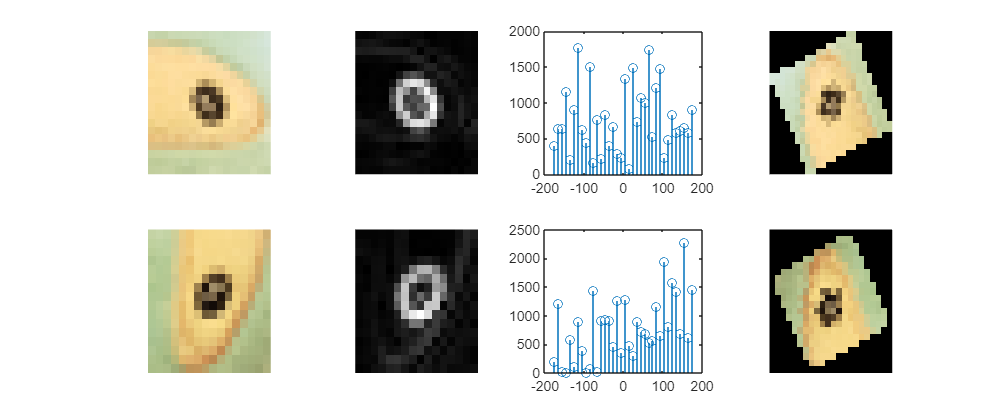

patch1 = '20201226_200728_patch.jpg';
patch2 = '20201226_200735_patch.jpg';

imgPatch1 = imresize(imread(patch1),0.05);
[Gmag1,Gdir1] = imgradient(rgb2gray(imgPatch1));

imgPatch2 = imresize(imread(patch2),0.05);
[Gmag2,Gdir2] = imgradient(rgb2gray(imgPatch2));

[~,~,bin] = histcounts(Gdir1, -180:10:180); % 36 bins

hist_count1 = zeros(1,36);
for ii=1:36
    tmp = Gmag1(bin==ii);
    hist_count1(ii) = sum(tmp, 'all');
end

[~,~,bin] = histcounts(Gdir2, -180:10:180); % 36 bins

hist_count2 = zeros(1,36);
for ii=1:36
    tmp = Gmag2(bin==ii);
    hist_count2(ii) = sum(tmp, 'all');
end

edges = -175:10:175;

fig3 = figure(10);
set(fig3,'Position', [100 100 1400 500]);

subplot(241); imshow(imgPatch1); 
subplot(242); imshow(mat2gray(Gmag1));
subplot(243); stem(edges, hist_count1); 

[~,I] = max(hist_count1);
subplot(244); imshow(imrotate(imgPatch1, -edges(I)));

subplot(245); imshow(imgPatch2); 
subplot(246); imshow(mat2gray(Gmag2));
subplot(247); stem(edges, hist_count2);

[~,I] = max(hist_count2);
subplot(248); imshow(imrotate(imgPatch2, -edges(I)));

### Orientation Normalization2

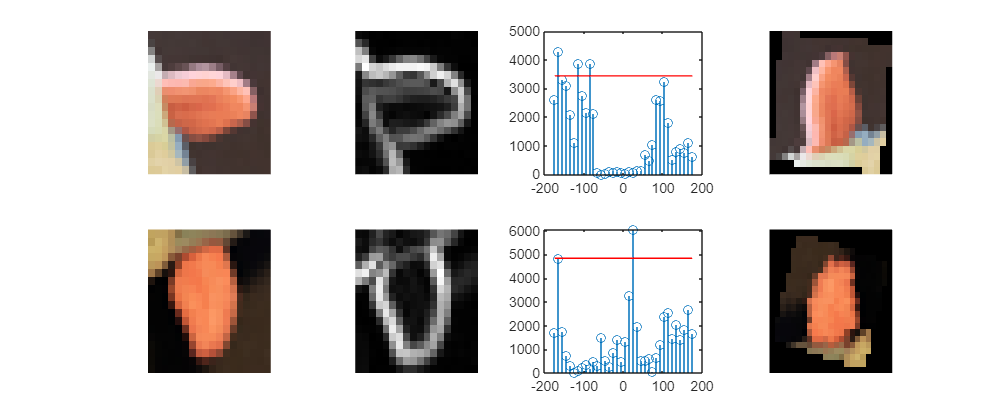

patch1 = '20201226_200728_patch2.jpg';
patch2 = '20201226_200735_patch2.jpg';

imgPatch1 = imresize(imread(patch1),0.05);
[Gmag1,Gdir1] = imgradient(rgb2gray(imgPatch1));

imgPatch2 = imresize(imread(patch2),0.05);
[Gmag2,Gdir2] = imgradient(rgb2gray(imgPatch2));

[~,~,bin] = histcounts(Gdir1, -180:10:180); % 36 bins

hist_count1 = zeros(1,36);
for ii=1:36
    tmp = Gmag1(bin==ii);
    hist_count1(ii) = sum(tmp, 'all');
end

[~,~,bin] = histcounts(Gdir2, -180:10:180); % 36 bins

hist_count2 = zeros(1,36);
for ii=1:36
    tmp = Gmag2(bin==ii);
    hist_count2(ii) = sum(tmp, 'all');
end

edges = -175:10:175;

fig3 = figure(11);
set(fig3,'Position', [100 100 1400 500]);

subplot(241); imshow(imgPatch1); 
subplot(242); imshow(mat2gray(Gmag1));
subplot(243); stem(edges, hist_count1); hold on;

thres_line = 0.8*max(hist_count1);
line(edges([1 end]), [thres_line thres_line],'color', 'r'); hold off;
[~,I] = sort(hist_count1, 'descend'); I = I(2);
subplot(244); imshow(imrotate(imgPatch1, -edges(I)));

subplot(245); imshow(imgPatch2); 
subplot(246); imshow(mat2gray(Gmag2));

subplot(247); stem(edges, hist_count2);
thres_line = 0.8*max(hist_count2);
line(edges([1 end]), [thres_line thres_line],'color', 'r'); hold off;

[~,I] = sort(hist_count2, 'descend'); I = I(2);
subplot(248); imshow(imrotate(imgPatch2, -edges(I)));

### Intensity Invariant

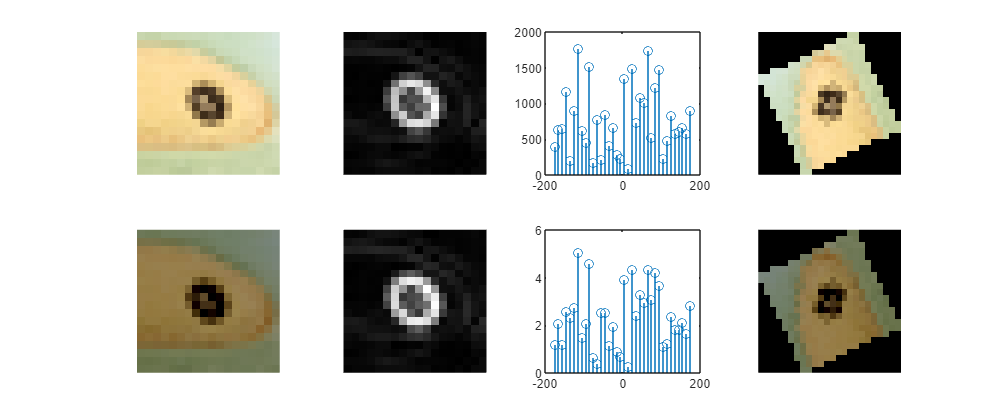

patch1 = '20201226_200728_patch.jpg';
imgPatch1 = imresize(imread(patch1),0.05);

imgPatch2 = im2double(imgPatch1);
imgPatch2 = imgPatch2*0.8 -0.2;

[Gmag1,Gdir1] = imgradient(rgb2gray(imgPatch1));
[Gmag2,Gdir2] = imgradient(rgb2gray(imgPatch2));

[~,~,bin] = histcounts(Gdir1, -180:10:180); % 36 bins

hist_count1 = zeros(1,36);
for ii=1:36
    tmp = Gmag1(bin==ii);
    hist_count1(ii) = sum(tmp, 'all');
end

[~,~,bin] = histcounts(Gdir2, -180:10:180); % 36 bins

hist_count2 = zeros(1,36);
for ii=1:36
    tmp = Gmag2(bin==ii);
    hist_count2(ii) = sum(tmp, 'all');
end

edges = -175:10:175;

fig3 = figure(12);
set(fig3,'Position', [100 100 1400 500]);


subplot(241); imshow(imgPatch1); 
subplot(242); imshow(mat2gray(Gmag1));
subplot(243); stem(edges, hist_count1); 

[~,I] = max(hist_count1);
subplot(244); imshow(imrotate(imgPatch1, -edges(I)));

subplot(245); imshow(imgPatch2); 
subplot(246); imshow(mat2gray(Gmag2));
subplot(247); stem(edges, hist_count2);

[~,I] = max(hist_count2);
subplot(248); imshow(imrotate(imgPatch2, -edges(I)));